% Cleanup!
clear all 
close all
clc

[MotionData]=ParseMatlabApp('nathan50hz.mat')

MotionData = struct with fields:
            Accel: [1251×3 double]
      Orientation: [1251×3 double]
           AngVel: [1251×3 double]
          t_Accel: [1251×1 double]
    t_Orientation: [1251×1 double]
         t_AngVel: [1251×1 double]
       accel_rate: 21.2766
      orient_rate: 21.2766
      AngVel_rate: 21.2766


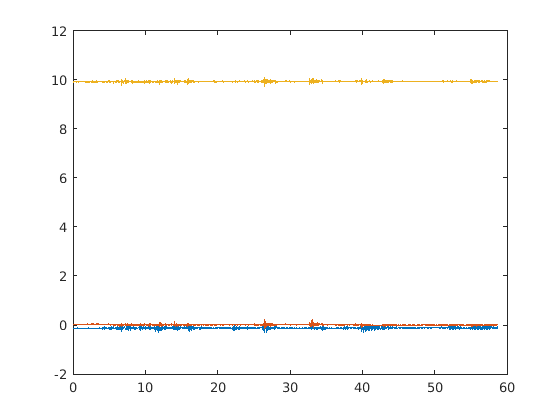

plot(MotionData.t_Accel, MotionData.Accel)

Fs = MotionData.accel_rate % in hertz

Fs = 21.2766

N = length(MotionData.t_Accel)

N = 1251

% FIlter data into 1 minute chunk
chunk_sz = 0 % time in seconds

chunk_sz = 0

chunks = 1

chunks = 1

front_trim = 10 % trim the first ten

front_trim = 10


% Trim the entire front
index_front = round(front_trim * Fs)+1

index_front = 214

MotionData.t_Accel = MotionData.t_Accel(index_front:end)

MotionData = struct with fields:
            Accel: [1251×3 double]
      Orientation: [1251×3 double]
           AngVel: [1251×3 double]
          t_Accel: [1038×1 double]
    t_Orientation: [1251×1 double]
         t_AngVel: [1251×1 double]
       accel_rate: 21.2766
      orient_rate: 21.2766
      AngVel_rate: 21.2766


MotionData.t_Accel = MotionData.t_Accel - MotionData.t_Accel(1);
MotionData.Accel = MotionData.Accel(index_front:end, :);

index_end = index_front + round(chunk_sz * Fs)

index_end = 214

%MotionData.t_Accel = MotionData.t_Accel(index_front:index_end)-MotionData.t_Accel(1)
N = length(MotionData.t_Accel)

N = 1038

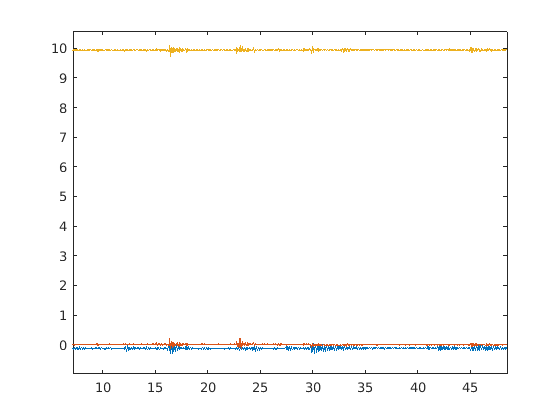

plot(MotionData.t_Accel, MotionData.Accel)

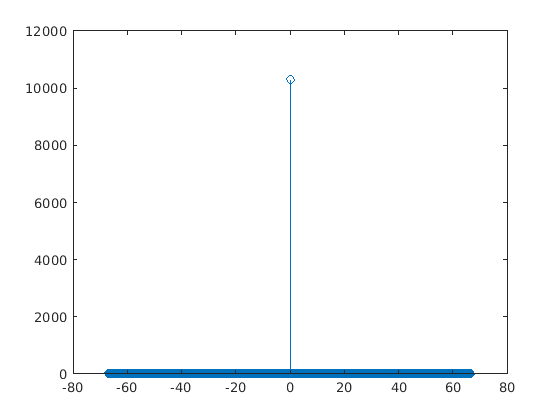

z_fft = fft(MotionData.Accel(:, 3));
z_fft_shift = fftshift(z_fft);
frequencies_shifted = Fs*linspace(-pi, pi-2/N*pi, N) + pi/N*mod(N,2);

stem(frequencies_shifted, abs(z_fft_shift))


maxk(abs(z_fft), 5)

ans = 	1.0e+04 *

    1.0317
    0.0004
    0.0004
    0.0004
    0.0004


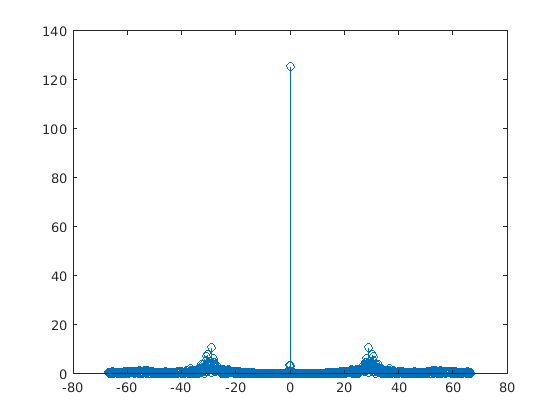

x_fft = fft(MotionData.Accel(:, 1));
x_fft_shift = fftshift(x_fft);
frequencies_shifted = Fs*linspace(-pi, pi-2/N*pi, N) + pi/N*mod(N,2);

stem(frequencies_shifted, abs(x_fft_shift))

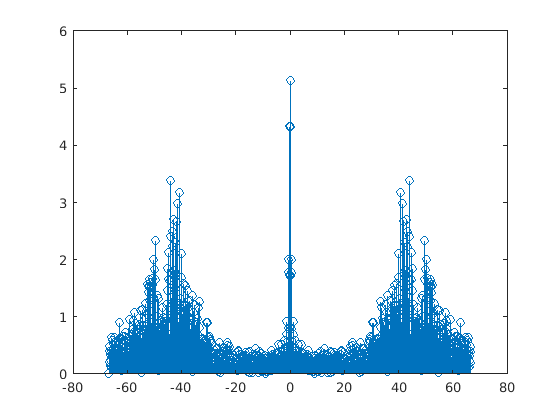

y_fft = fft(MotionData.Accel(:, 2));
y_fft_shift = fftshift(y_fft);
frequencies_shifted = Fs*linspace(-pi, pi-2/N*pi, N) + pi/N*mod(N,2);

stem(frequencies_shifted, abs(y_fft_shift))